# Descriptive Statistics and Visualization

In an experiment on sleep disorders, a scientist administers a new formula of sleeping medication to 35 test subjects and records how many of them sleep continuously for at least 8 hours. The scientist replicates the experiment a total of 15 times (with a different group of 35 test subjects each time). The counts recorded by the scientist are

D=[11 9 10 12 9 15 10 7 13 16 10 4 7 9 11]

D =     11     9    10    12     9    15    10     7    13    16    10     4     7     9    11


## Descriptive Statistics

The scientist computes several measures of central tendency.

Mean=mean(D)

Mean = 10.2000

Median=median(D)

Median = 10

Mode=mode(D)

Mode = 9

Next, they compute the variance and standard deviation

Variance=var(D,1)

Variance = 8.8267

StandardDeviation=std(D,1)

StandardDeviation = 2.9710

They also seek a robust measure of variability, so they compute the range, quartiles, and interquartile range

Range=max(D)-min(D)

Range = 12

Q=quantile(D,[0.25,0.50,0.75])

Q =     9.0000   10.0000   11.7500


InterQuartileRange=Q(3)-Q(1)

InterQuartileRange = 2.7500

Next, they compute the skewness and Bowley's measure of skewness

Skewness=skewness(D)

Skewness = 0.0647

Bowley=(Q(3)+Q(1)-2*Q(2))/InterQuartileRange

Bowley = 0.2727

Finally, they compute the kurtosis of the data set.

Kurtosis=kurtosis(D)

Kurtosis = 2.9340

## Visualization

After computing the suite of descriptive statistics, the scientist visualizes the data with a histogram

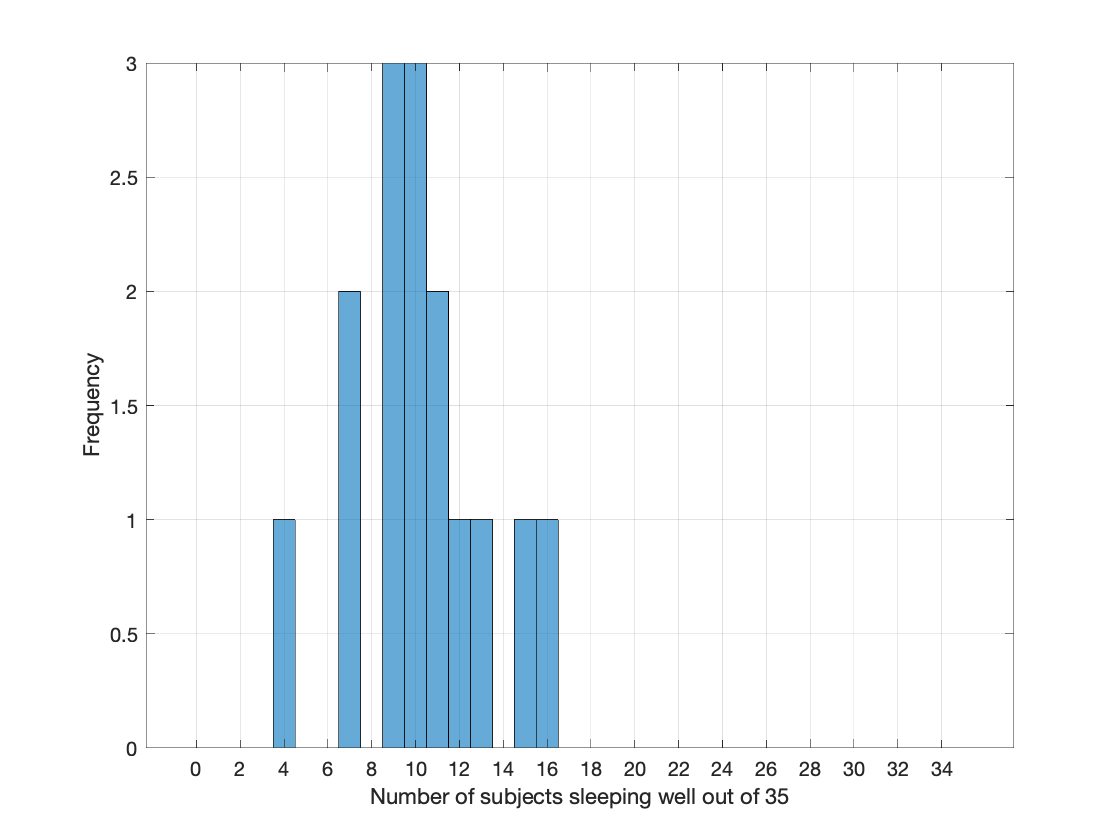

figure(1)
histogram(D,[-0.5:1:35.5])
xticks([0:2:35])
grid on
xlabel('Number of subjects sleeping well out of 35')
ylabel('Frequency')

The scientist produces a similar histogram that is scaled so that bar heights represent relative frequencies instead of absolute frequencies.

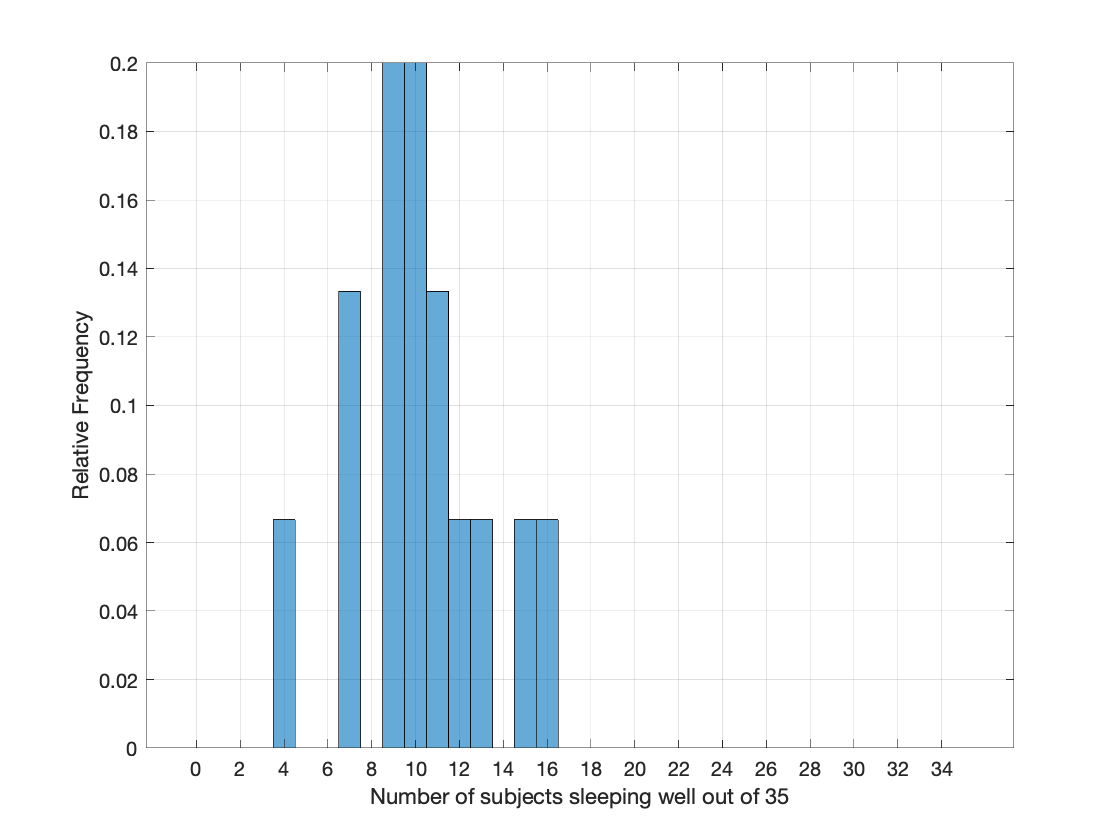

figure(2)
histogram(D,[-0.5:1:35.5],"Normalization","pdf")
xticks([0:2:35])
grid on
xlabel('Number of subjects sleeping well out of 35')
ylabel('Relative Frequency')

Finally, they produce a box and whisker plot in order to summarize the relationship between the min, max, and quartiles of the data

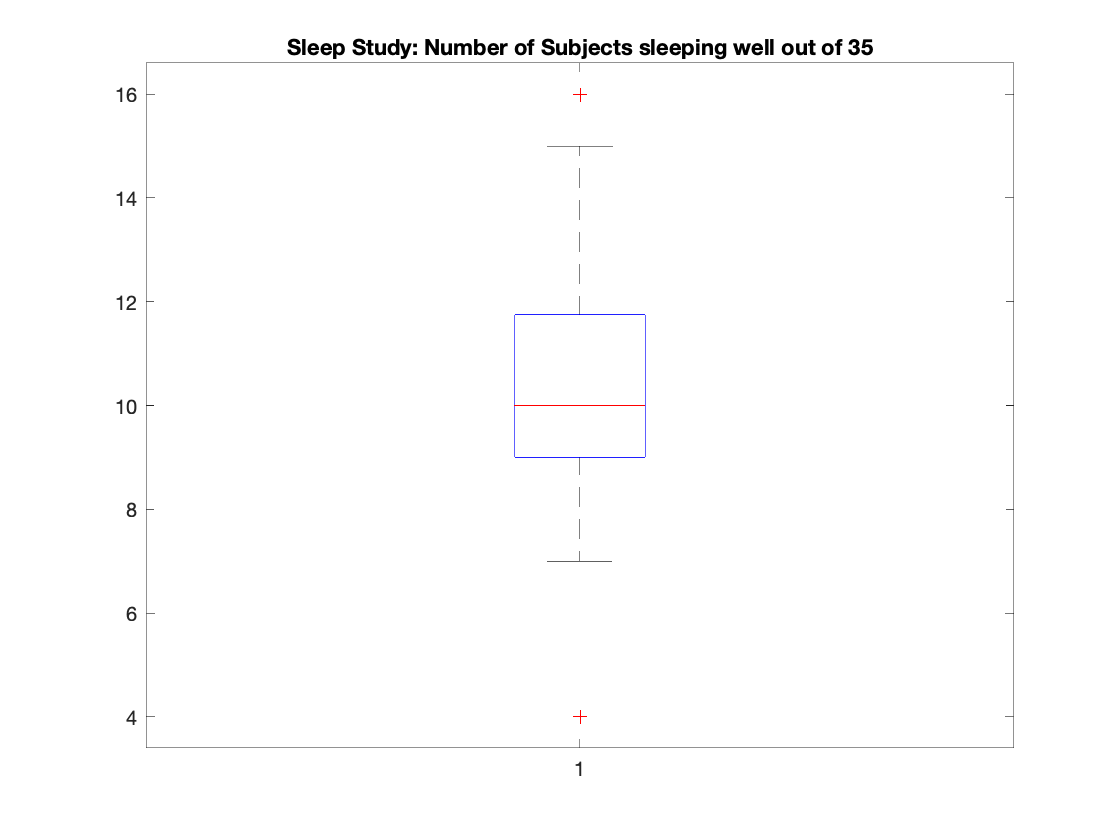

figure(3)
boxplot(D)
title('Sleep Study: Number of Subjects sleeping well out of 35')